# $\ell_1$ norm optimized solution of the system of equations $A\mathbf{x}=\mathbf{b}$ is sparse.

# Compare least $\ell_1$ and $\ell_2$ norm solution of $A\mathbf{x}=\mathbf{b}$

clearvars

Construct $A$ and $\mathbf{b}$

n = 10;
m = 3;
A = randi([-5,5],m,n);
b = A*randi([-3,3],n,1)

b =    -28
    21
    21


Find the least $\ell_2$ norm solution (using pseudo inverse)

x_2 = pinv(A)*b;

Find the least $\ell_1$ norm solution (using ADMM)

maxIter = 400;
rho = 1.6;

B1 = A'*pinv(A*A');
B1b = B1*b;
B2 = B1*A;
converged = false;
dz = 1e-6;

Initialize the $\mathbf{z}$ and $\mathbf{u}$ vectors

Z0 = rand(n,1);
U0 = rand(n,1);

for i = 1:maxIter
    % X update - using Shrinkage
    c = Z0 - U0;
    X1 = c - sign(c)/rho;
    X1(sign(X1) ~= sign(c)) = 0;
    % Z update - using Projection
    mu = X1 + U0;
    Z1 = (eye(n) - B2)*mu + B1b;
    % U update - using gradient
    U1 = U0 + (X1 - Z1);
    if(norm(Z1-Z0) <= dz)
        converged = true;
        break
    end
    fprintf("iter : %d \t dz : %f dxz : %f \n",i,norm(Z1-Z0),norm(X1-Z0));
    % fprintf("iter : %d \t dz : %f\n",i,norm(X1-Z0));
    Z0 = Z1; 
    U0 = U1;
end

iter : 1 	 dz : 4.705226 dxz : 1.369830 
iter : 2 	 dz : 0.796924 dxz : 3.478089 
iter : 3 	 dz : 0.689179 dxz : 0.708165 
iter : 4 	 dz : 0.371754 dxz : 0.402278 
iter : 5 	 dz : 0.353023 dxz : 0.359279 
iter : 6 	 dz : 0.196943 dxz : 0.206037 
iter : 7 	 dz : 0.097210 dxz : 0.143178 
iter : 8 	 dz : 0.089849 dxz : 0.115345 
iter : 9 	 dz : 0.097634 dxz : 0.100401 
iter : 10 	 dz : 0.091017 dxz : 0.092670 
iter : 11 	 dz : 0.086026 dxz : 0.088781 
iter : 12 	 dz : 0.085462 dxz : 0.086835 
iter : 13 	 dz : 0.085202 dxz : 0.085847 
iter : 14 	 dz : 0.084865 dxz : 0.085330 
iter : 15 	 dz : 0.084863 dxz : 0.085048 
iter : 16 	 dz : 0.084863 dxz : 0.084888 
iter : 17 	 dz : 0.084734 dxz : 0.084794 
iter : 18 	 dz : 0.084637 dxz : 0.084735 
iter : 19 	 dz : 0.084631 dxz : 0.084698 
iter : 20 	 dz : 0.084656 dxz : 0.084674 
iter : 21 	 dz : 0.084658 dxz : 0.084658 
iter : 22 	 dz : 0.084642 dxz : 0.084648 
iter : 23 	 dz : 0.084628 dxz : 0.084640 
iter : 24 	 dz : 0.084625 dxz : 0.084636 
i

x_1 = X1;

if(converged == true)
    fprintf("L1 norm optimized solution found after %d iterations. \n",i);
elseif(converged == false)
    fprintf("Convergence failed\n")
    fprintf("Try : increasing the no: iteration, increasing the convergence tol value, changing rho\n");
end

L1 norm optimized solution found after 215 iterations. 


Plot to check the solution vector $X$ and surrogate variable $Z$

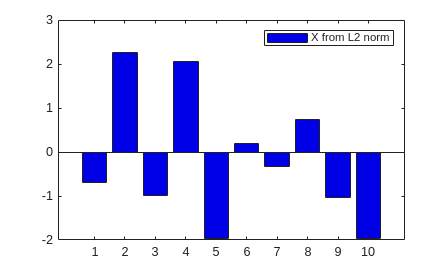

b2 = bar(x_2);%;hold on;
b2.FaceColor = [0 0 0.9];
legend("X from L2 norm")

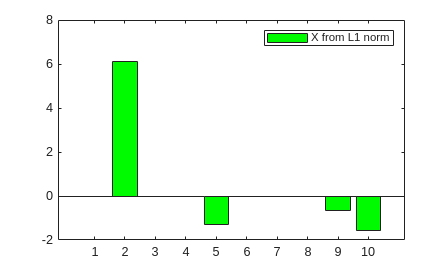


b1 = bar(x_1);%hold off
b1.FaceColor = [0 0.98 0];
legend("X from L1 norm")

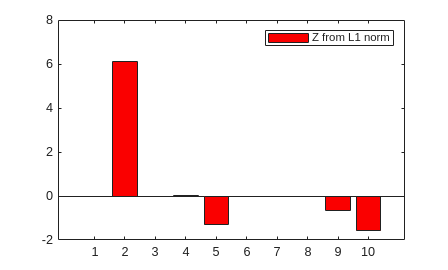


b1 = bar(Z1);%hold off
b1.FaceColor = [0.98 0 0];
legend("Z from L1 norm")

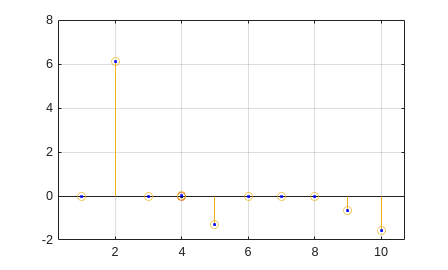


plot(X1,'k.');hold on
stem(X1)
stem(Z1)
plot(Z1,'b.');hold off
grid on

Check the error vector $A\mathbf{x}-\mathbf{b}$

e1 = A*x_1-b

e1 = 1.0e-04 *

    0.2364
   -0.2869
    0.6553


e2 = A*x_2-b

e2 = 1.0e-14 *

   -0.7105
    0.7105
         0


Check the sparsity of the solution

sum(x_1 ~= 0)

ans = 4

sum(x_2 ~= 0)

ans = 10

cd("/media/user/DATA4LINUX/new1/Repos/Mine/MFC4_22MAT230/")
mlxfile = matlab.desktop.editor.getActive().Filename;
outfile = mlxfile + ".pdf"

outfile = "/media/user/DATA4LINUX/new1/Repos/Mine/MFC4_22MAT230/U1_Comparison_L1_L2_norm_Matlab_coding.mlx.pdf"

export(matlab.desktop.editor.getActive().Filename, outfile);